## A Low-pass RC filter

By combining resistors, capacitors, and inductors in special ways, you can design circuits that are capable of passing certain frequencies of signals while rejecting others.

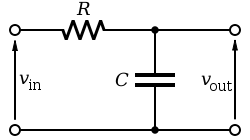

Source: Wikipedia

This simle RC filter acts as a low-pass filter - it passes low frequencies but rejects high frequencies.

**How does it work?**

To figure out how this circuit works, we find the ***transfer function.*** Hint: Use the voltage divider formula.

## 
$$V_{\mathrm{out}} =\frac{1/\left(j\omega C\right)}{R+1/\left(j\omega C\right)\text{ }}V_{\mathrm{in}} =\frac{1}{1+j\omega \mathit{RC}}V_{\mathrm{in}}$$


The transfer function is then found by rearranging the equation:

## 
$$H=\frac{V_{\mathrm{out}} }{V_{\mathrm{in}} }=\frac{1}{1+j\omega \mathit{RC}}$$


## 
$$H=\frac{V_{\text{out}} }{V_{\text{in}} }=\frac{1}{1+j\omega \tau },\text{     }\tau =\mathit{RC}$$


## 
$$H=\frac{V_{\text{out}} }{V_{\text{in}} }=\frac{1}{1+j\omega /\omega_c },\text{    }\omega_c =\frac{1}{\mathit{RC}}$$


The magnitude and phase of H are:

## 
$$\left|H\right|=\left|\frac{V_{\text{out}} }{V_{\text{in}} }\right|=\frac{1}{\sqrt{1+\tau^2 \omega^2 }}$$


## 
$$\mathrm{arg}\left(H\right)=\varphi =-{\mathrm{tan}}^{-1} \left(\frac{\omega }{\omega_c }\right)$$


Here, $\tau$ is called the time constant, and $\omega_c$ is called the ***angular cutoff frequency*** of the circuit. It is related to ***standard frequency*** by $\omega_c =2\pi f_c$.

**Frequency response of a first order RC filter**

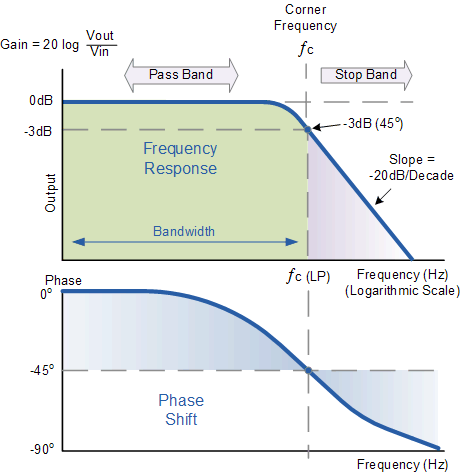

Source: [https://www.electronics-tutorials.ws/filter/filter_2.html](https://www.electronics-tutorials.ws/filter/filter_2.html)

The **bode plot** in the above shows the frequency respose of a typical low pass RC filter.

The **phase vs. frequency plot** shows that the capacitor produces a delay. At low frequency, the output floows the input. As the frequency increases, the output starts lagging the input. As the the frequency goes to infinity, the phase lag approaches 90 degrees.

**Example**

Compute the cut-off frequency of the RC filter with ***R=5 Kohms*** and ***C=47 nF***

## 
$$f_c =\frac{\omega_c }{2\pi }=\frac{1}{2\pi \mathit{RC}}=\frac{1}{2\pi \left(5∗{10}^3 \text{ }\Omega \right)\left(47∗{10}^{-9} \text{ }F\right)}$$


num = 1;
denom = 2*pi*5*1e3*47*1e-9;
fc = num/denom;
disp(fc)

  677.2551



## 
$$f_c =677\ldotp 26\text{ }\mathit{Hz}$$


**What is the limitation of a first-order RC filter?**

- The attenuation after the cut-off frequency is very gradual (A roll-off of -20dB/Decade).

- That is fine if you want to filter out very high frequencies.

- But if you desire a sharper cut-off, you need to build a more sophisticated circuit.

- By cascading the simple RC filters (increasing the filter order) we can obtain a sharper filter.

It is impossible to build an ideal filter. The practical filters have to consider tradeoffs between different aspects of the filter that impact the overall quality of the filter.

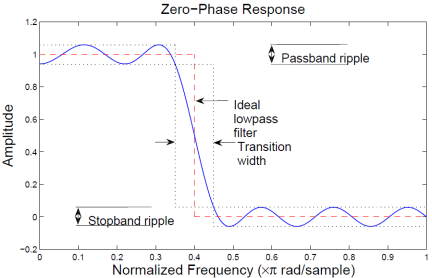

Source: Mathworks, Inc.

**Digital filter types**

These are the digital equivalents of the analog filters we have seen before.

The most common IIR filters are:

- Butterworth

- Chebyshev

- Bessel

- Elliptic

The transfer function of an LTI system (inlcuding filters) can be represented in the Laplace domain by:

## 
$$H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}=\frac{B_m s^m +B_{m-1} s^{m-1} +\ldotp \ldotp \ldotp \ldotp +B_0 }{A_n s^n +A_{n-1} s^{n-1} +\ldotp \ldotp \ldotp \ldotp +A_0 }$$


People (Butterworth, Chebyshev, etc.) came up with different variations of the above transfer function to obtain a specific frequency response. 

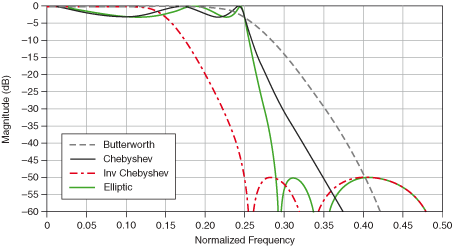

Source: [https://www.physik.uzh.ch](https://www.physik.uzh.ch)

At the end of the day, all you need is to find the right **filter coefficients** to make your desired digital filter.

And MATLAB does that for you!

**The most commonly used digital filter: Butterworth**

help butter

 butter Butterworth digital and analog filter design.
    [B,A] = butter(N,Wn) designs an Nth order lowpass digital
    Butterworth filter and returns the filter coefficients in length
    N+1 vectors B (numerator) and A (denominator). The coefficients
    are listed in descending powers of z. The cutoff frequency
    Wn must be 0.0 < Wn < 1.0, with 1.0 corresponding to
    half the sample rate.
 
    If Wn is a two-element vector, Wn = [W1 W2], butter returns an
    order 2N bandpass filter with passband  W1 < W < W2.
    [B,A] = butter(N,Wn,'high') designs a highpass filter.
    [B,A] = butter(N,Wn,'low') designs a lowpass filter.
    [B,A] = butter(N,Wn,'stop') is a bandstop filter if Wn = [W1 W2].
 
    When used with three left-hand arguments, as in
    [Z,P,K] = butter(...), the zeros and poles are returned in
    length N column vectors Z and P, and the gain in 

**Steps for creating a butterworth filter in MATLAB**

Let's assume that we have a signal sampled at 1000 Hz, therefore the Nyquist frequency of the signal is 500 Hz.

fs = 1000;

**1. Determine the cut-off frequency (fc):**

fc = 120; % Cut-off frequency for the low-pass filter: 250 Hz

**2. Normalize the fc:**

wn = fc/(fs/2);

**3. Determine the filter order:**

N = 3;

**4. Obtain the filter coefficients**

[b, a] = butter(N, wn)

b =     0.0286    0.0859    0.0859    0.0286


a =     1.0000   -1.5189    0.9600   -0.2120


**5. Examine the bode plot to verify (hint: use *****freqz***** function)**

help freqz

 freqz Frequency response of digital filter
    [H,W] = freqz(B,A,N) returns the N-point complex frequency response
    vector H and the N-point frequency vector W in radians/sample of
    the filter:
 
                jw               -jw              -jmw
         jw  B(e)    b(1) + b(2)e + .... + b(m+1)e
      H(e) = ---- = ------------------------------------
                jw               -jw              -jnw
             A(e)    a(1) + a(2)e + .... + a(n+1)e
 
    given numerator and denominator coefficients in vectors B and A.
 
    [H,W] = freqz(SOS,N) returns the N-point complex frequency response
    given the second order sections matrix SOS. SOS is a Kx6 matrix, where
    the number of sections, K, must be greater than or equal to 2. Each row
    of SOS corresponds to the coefficients of a second order filter. From
    the transfer function displayed above, the ith row of the SOS matrix
    corresponds to [bi(1) bi(2) bi

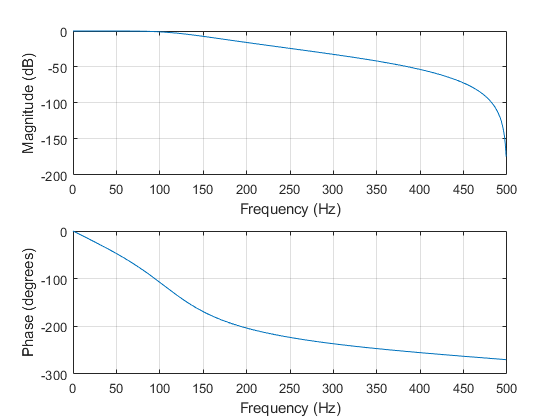

freqz(b, a, 500, fs)

help fvtool

 fvtool Filter Visualization Tool (FVTool)
    FVTool is a Graphical User Interface (GUI) that allows you to analyze
    digital filters.  
 
    fvtool(B,A) launches the Filter Visualization Tool and computes the
    Magnitude Response for the filter defined by numerator and denominator
    coefficients in vectors B and A.
 
    fvtool(SOS) launches the Filter Visualization Tool and computes the
    Magnitude Response for the filter defined by the second order sections
    matrix, SOS. SOS is a Kx6 matrix, where the number of sections, K, must
    be greater than or equal to 2.
 
    fvtool(D) launches the Filter Visualization Tool and computes the
    Magnitude Response for the digital filter D. You design a digital
    filter, D, by calling the designfilt function.
  
    fvtool(B,A,B1,A1,SOS,SOS1,D1,D2,...) will perform an analysis on
    multiple filters.
 
   

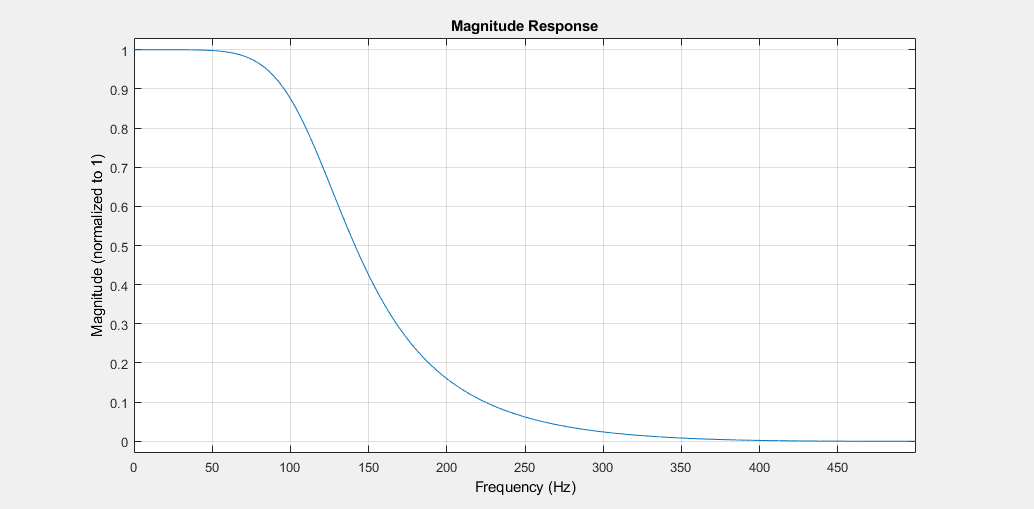

hfvt = fvtool(b,a);
set(hfvt,'FrequencyScale','linear','NormalizedFrequency','off','NormalizeMagnitudeto1','on','Fs',fs,'MagnitudeDisplay','magnitude');

## Example 1:

Visualize the effect of filter order (N) on the frequency response.

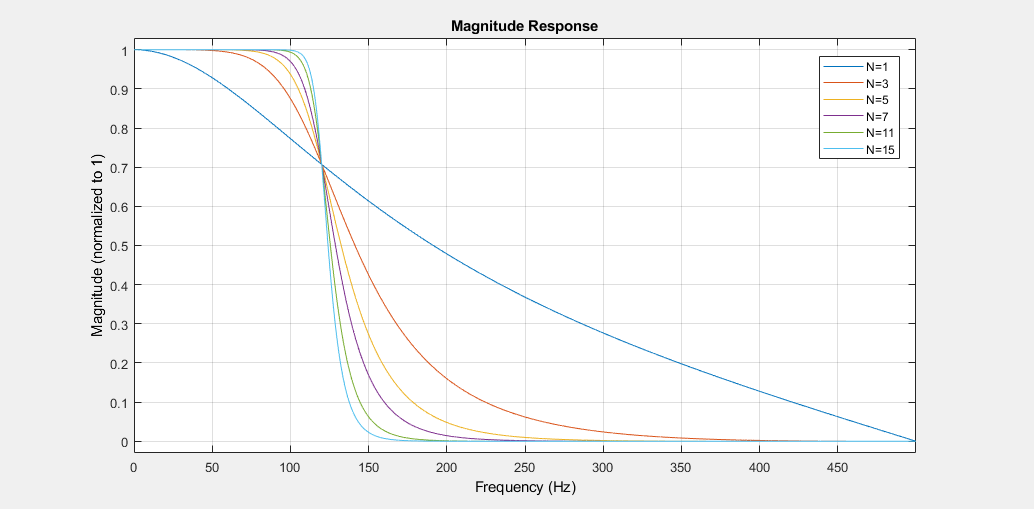

fs = 1000;
fc = 120;
wn = fc/(fs/2);
N = [1, 3, 5, 7, 11, 15];

A = {};
B = {};
for i=1:numel(N)
    [b,a] = butter(N(i), wn);
    B{i} = b;
    A{i} = a;
end

hfvt = fvtool(B{1},A{1},B{2},A{2},B{3},A{3},B{4},A{4},B{5},A{5},B{6},A{6});
set(hfvt,'FrequencyScale','linear','NormalizedFrequency','off','NormalizeMagnitudeto1','on','Fs',fs,'MagnitudeDisplay','magnitude');
legend(hfvt,'N=1','N=3','N=5','N=7','N=11','N=15')

## Example 2:

Desing and implement a "digital notch filter" to remove the 60Hz noise component from an EEG signal (Sampling rate=256 Hz)

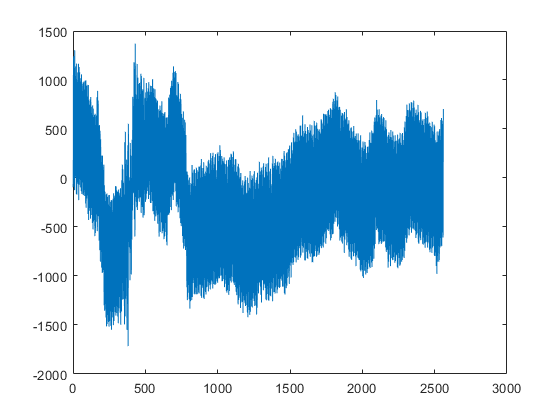

load hum.mat
figure; plot(eeg)

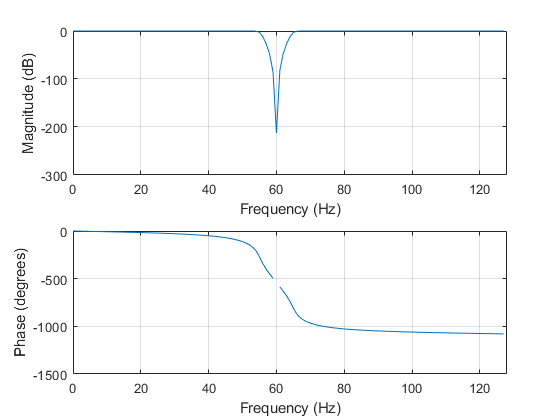

% Design a butterworth type notch filter
fs = 256;
fc_low = 55;
fc_high = 65;
wn = [fc_low fc_high]/(fs/2);
N = 6;
[b,a] = butter(N,wn,'stop');

% Check out the frequency response
freqz(b,a,fs/2,fs)

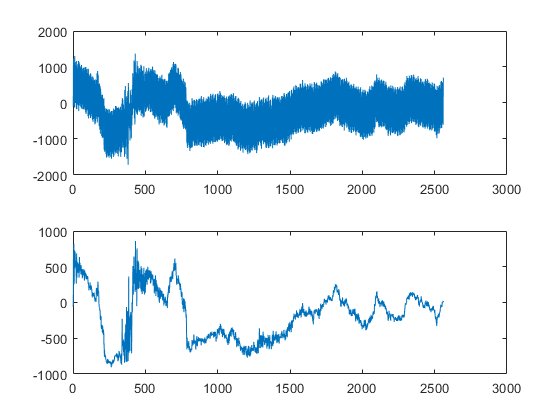


% Filter the signal
eeg_filtered = filter(b,a,eeg);

% Plotting
figure;
subplot(211); plot(eeg); title('Raw eeg')
subplot(212); plot(eeg_filtered); title('Filtered eeg')

## Exercise 1:

- Create signal consists of 3 sinusoidal components: 5 Hz, 80 Hz, and 200 Hz (Make sure to choose a sampling frequency that is several times higher than **twice of the max frequency** component in your signal)

- Design and implement a low pass filter so that only the 5 Hz component will remain

- Design and implement a band pass filter so that only the 80 Hz component will remain

- Design and implement a high pass filter so that only the 200 Hz component will remain

% Solution here...